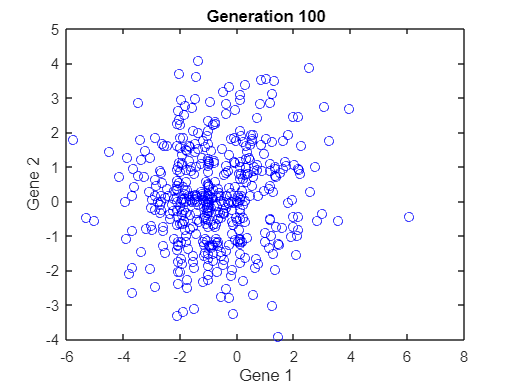

5%clear; close; clc;

% optimization parameters
population_size = 500; % size of the population
num_generations = 100; % number of generations to itterate over
num_genes = 8; % number of design variables
crossover_rate = .8; % amount of recombination of surviors genes that occurs
mutation_rate = .5+.01; % rate of random changes in genes

% Initialization
population = rand(num_genes, population_size) * 10 - 5; % initialize a random population between zero and 5

% Optimization loop
for generation = 1:num_generations
    % evaluate fittness
    fitness = objective_function(population); % objective function
    fitness = fitness - min(fitness); % normalize with respect to 0 such that there are not negative fitnesses
    inverse_fitness = 1./(fitness+1); % compute inverse of fitness because we need values in range 0 to 1 (this wont work for negative fitnesses)


    % selection
    probabilities = inverse_fitness / sum(inverse_fitness);
    cumulative_probabilities = cumsum(probabilities);
    % create mating pool (cull the non-survivors)
    mating_pool = zeros(size(population));
    for i = 1:population_size
        r = rand;
        selected_index = find(cumulative_probabilities >= r, 1);
        mating_pool(:, i) = population(:, selected_index);
    end

    
    % crossover
%     new_population = zeros(size(population));
%     for i = 1:2:population_size
%         parent1 = mating_pool(:, i);
%         if i+1 <= population_size
%             parent2 = mating_pool(:, i+1);
%         else
%             parent2 = mating_pool(:, 1);
%         end
%         if rand < crossover_rate
%             crossover_point = randi([1, num_genes-1]);
%             new_population(:, i) = [parent1(1:crossover_point); parent2(crossover_point+1:end)];
%             new_population(:, i+1) = [parent2(1:crossover_point); parent1(crossover_point+1:end)];
%         else
%             new_population(:, i) = parent1;
%             new_population(:, i+1) = parent2;
%         end
%     end

    % corssover (vecotrized)
    num_crossovers = round(crossover_rate * population_size / 2) * 2; % ensure even number
    crossover_indices = randperm(population_size, num_crossovers);
    parents1 = mating_pool(:, crossover_indices(1:2:end));
    parents2 = mating_pool(:, crossover_indices(2:2:end));
    crossover_points = randi([1, num_genes-1], 1, num_crossovers/2);
    
    new_population = mating_pool;
    for i = 1:num_crossovers/2
        cp = crossover_points(i);
        new_population(:, crossover_indices(2*i-1)) = [parents1(1:cp, i); parents2(cp+1:end, i)];
        new_population(:, crossover_indices(2*i)) = [parents2(1:cp, i); parents1(cp+1:end, i)];
    end

    % mutation
%     for i = 1:population_size
%         for j = 1:num_genes
%             if rand < mutation_rate
%                 new_population(j, i) = new_population(j, i) + randn;
%             end
%         end
%     end
    % mutation 
    % mutate random subset of the population by a random amount
    %new_population(rand(num_genes,population_size) < mutation_rate) = new_population + randn(num_genes,population_size);
    mutation_mask = rand(num_genes, population_size) < mutation_rate;
    new_population = new_population + mutation_mask .* randn(num_genes, population_size);

    % update population
    population = new_population;
    % visualize
    clf;
    plot(population(1, :), population(2, :), 'bo');
    title(['Generation ', num2str(generation)]);
    xlabel('Gene 1');
    ylabel('Gene 2');
    drawnow;
end


% visualize final solution
fitness = objective_function(population);
[best_fitness, best_index] = min(fitness);
best_solution = population(:, best_index);
disp('Best solution found:');

Best solution found:


disp(best_solution);

   -0.1978
   -0.0035
    0.1942
   -0.0276
   -0.0166
   -0.0661
   -0.0381
   -0.8672



disp('Best fitness:');

Best fitness:


disp(best_fitness);

   18.8060



function [f] = objective_function(x)
    %f = x(1,:) * (sin(x(1,:)/100*(2*pi)).^2 + 1) .*x(2,:); % cost function
    A = 10;
%     f = A*size(x,2)
%     for i = 1:length(x) 
%         f = f + x(i).^2 - A * cos(2*pi*x(i));
%     end
    f = A*size(x,1)+ sum(x.^2 - A * cos(2*pi*x),1);
    %c = [x(2,:), x(1,:)]/100; % const function gradient
    %c = 100*[(x(2,:)*(sin((pi*x(1,:))/50)^2 + 1))/100 + (pi*x(1,:)*x(2,:)*cos((pi*x(1,:))/50)*sin((pi*x(1,:))/50))/2500, (x(2,:)*(sin((pi*x(1,:))/50)^2 + 1))/100 + (pi*x(1,:)*x(2,:)*cos((pi*x(1,:))/50)*sin((pi*x(1,:))/50))/2500];
end